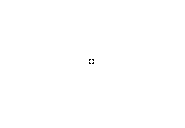


% 设计程序实现对图1，实现去除图像中的噪声。
% 使用先开后闭的方法，先用开运算去除小的噪声，再用闭运算消除指纹中的断裂
% 开闭操作的结构元应该是相同的，这样才能保证闭操作后的图像与开操作前的图像在非噪点的位置基本一致。
% 因为此处需要去除的噪点为小圆点的形状，因此采用'disk'结构元比较合适
r = 2;
I = imread('fingerprint.jpg');
I_open = imopen(I,strel('arbitrary',r));
figure(),imshow(strel('disk',r).Neighborhood);

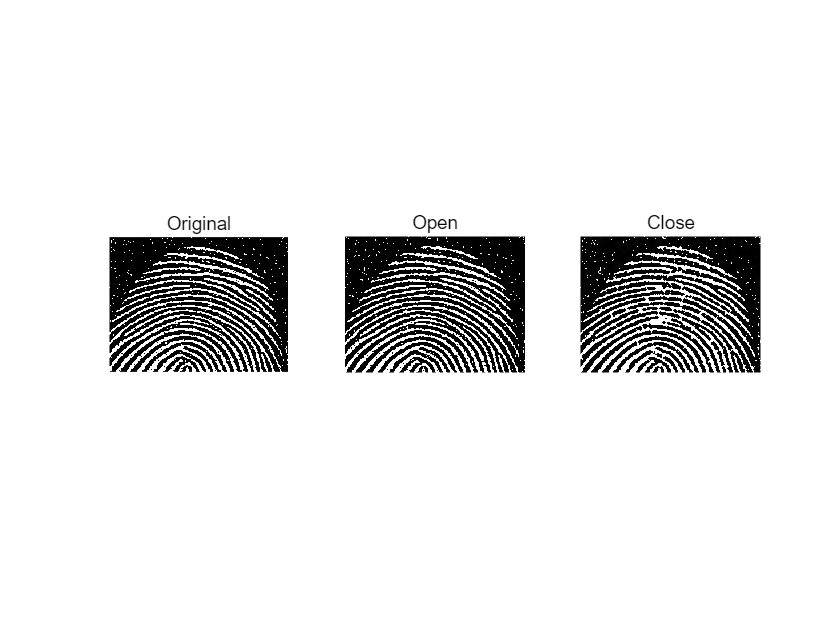

I_close = imclose(I_open,strel('disk',r));
figure, subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), imshow(I_open), title('Open');
subplot(1,3,3), imshow(I_close), title('Close');

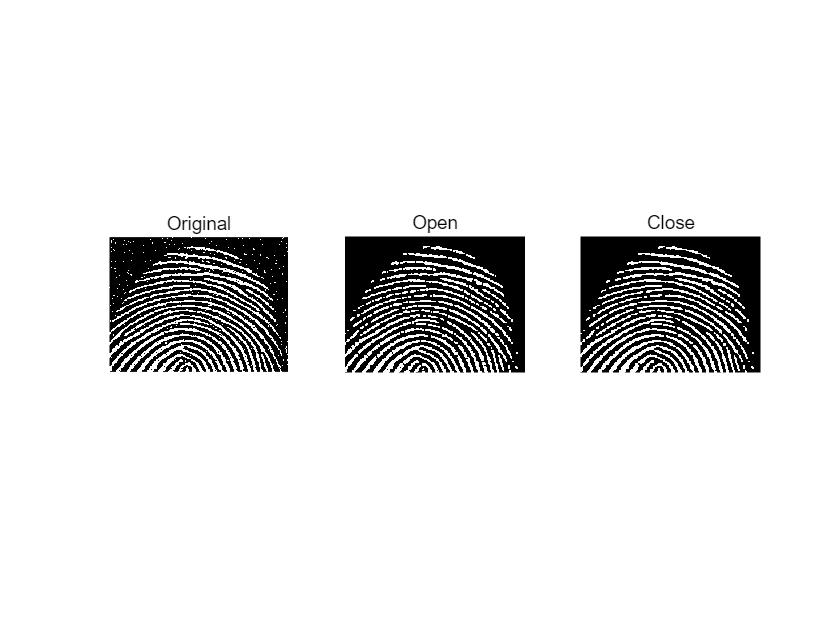

clear;
NHOOD = [1,1,1;1,1,1;1,1,1];
I = imread('fingerprint.jpg');
a = strel('arbitrary', NHOOD);
I_open = imopen(I,a);
I_close = imclose(I_open,a);
figure, subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), imshow(I_open), title('Open');
subplot(1,3,3), imshow(I_close), title('Close');

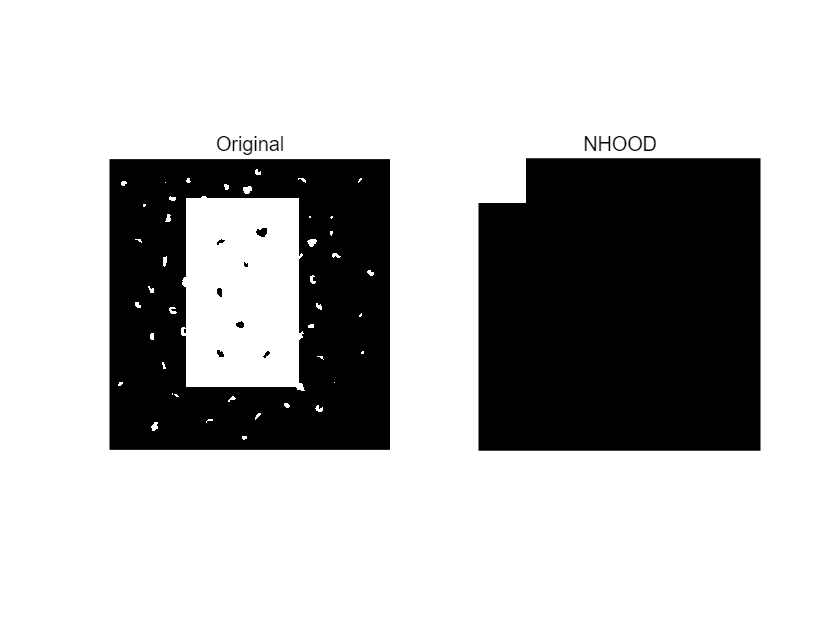


% 设计程序，实现去除图3中的矩形区域外的噪声，并填充矩形区域内部了
clear;
I = imread('rec.jpg');
% 估计矩形区域的大小，构造一个较大的矩形结构元素
row = 100;
col = 105;
NHOOD = ones(row,col);
% 将NHOOD放到黑色背景上
img = zeros(size(I));
img(1:row,1:col) = NHOOD;
figure(), subplot(1,2,1), imshow(I), title('Original');
subplot(1,2,2), imshow(img), title('NHOOD');

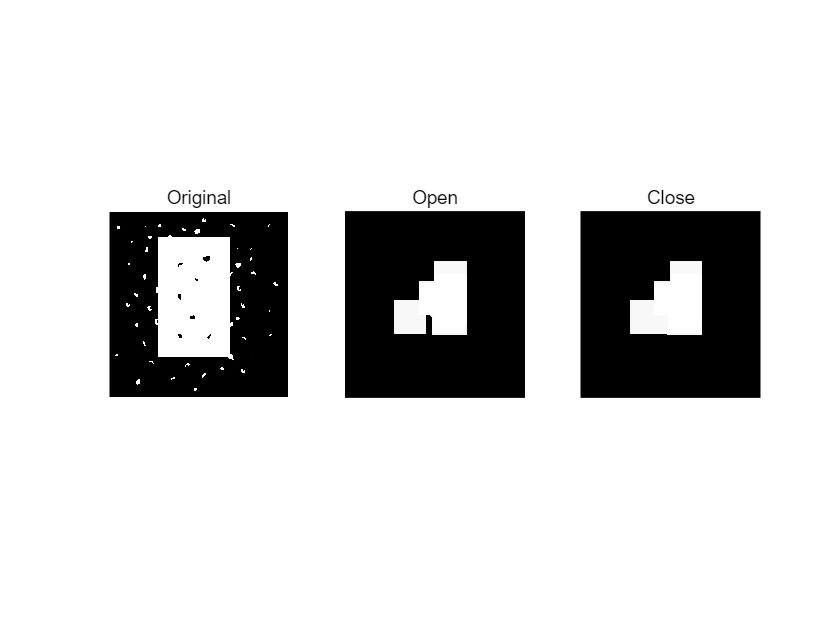

se = strel('arbitrary',NHOOD);
I_open = imopen(I,se);
I_close = imclose(I_open,se);
figure, subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), imshow(I_open), title('Open');
subplot(1,3,3), imshow(I_close), title('Close');

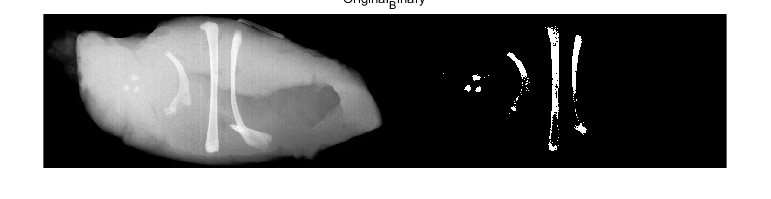

clear;
I = im2double(imread('chicken_bone.jpg'));
% 设置阈值

thres = 0.79;
I_b = imbinarize(I, thres);
% 并排放置图像
figure(),imshowpair(I, I_b, 'montage'), title('Original_Binary');

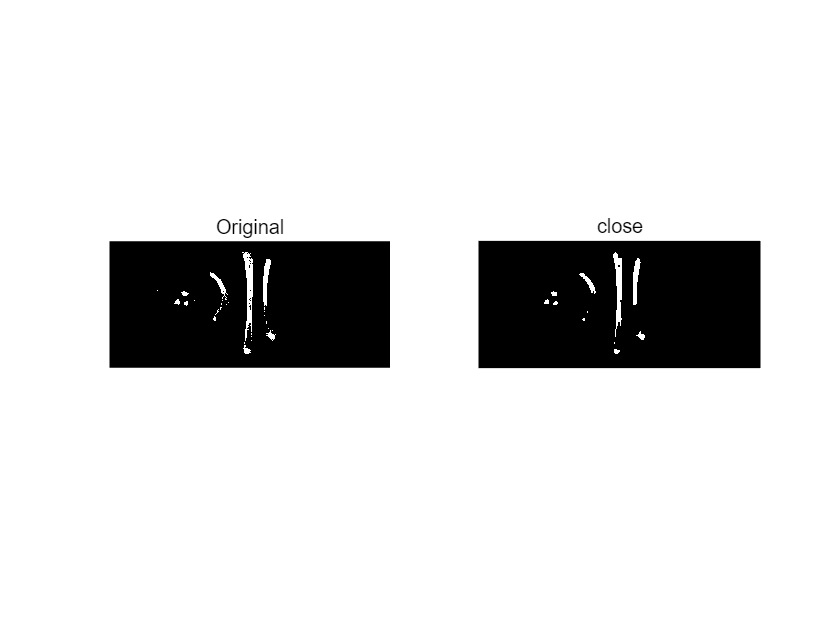

% 去除杂点
NHOOD = ones(3,3);
se = strel('arbitrary',NHOOD);
I_b_open = imopen(I_b, se);
I_b_close = imclose(I_b_open, se);
figure(), subplot(1,2,1), imshow(I_b), title('Original');
subplot(1,2,2), imshow(I_b_close), title('close');

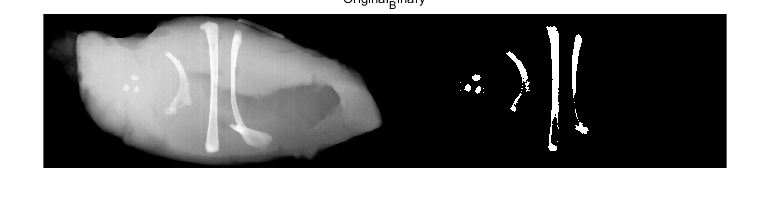


% 设置阈值

thres = 0.78;
I_temp = I+I_b_close/40;
I_temp = medfilt2(I_temp);
I_temp(I_temp > 1) = 1;
I_b = imbinarize(I_temp, thres);

% 并排放置图像
figure(),imshowpair(I_temp, I_b, 'montage'), title('Original_Binary');

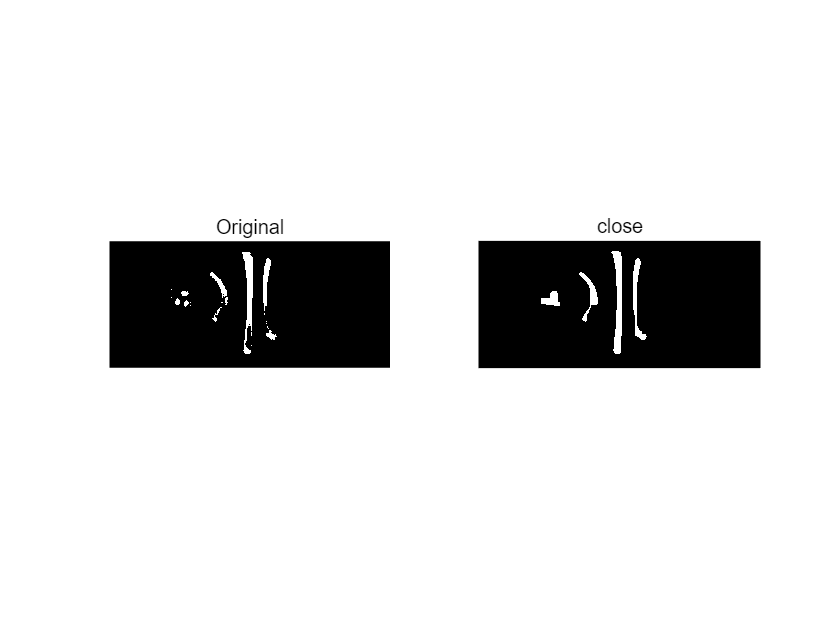

% NHOOD = ones(10,20);
se = strel('rectangle', [40, 20]);
I_b_close = imclose(I_b, se);
% I_b_open1 = imopen(I_b_close, se);
figure(), subplot(1,2,1), imshow(I_b), title('Original');
subplot(1,2,2), imshow(I_b_close), title('close');

bone = bwarea(I_b_close)

bone = 9194

[r,c] = size(I)

r = 321

c = 712

bone/(r*c)

ans = 0.0402

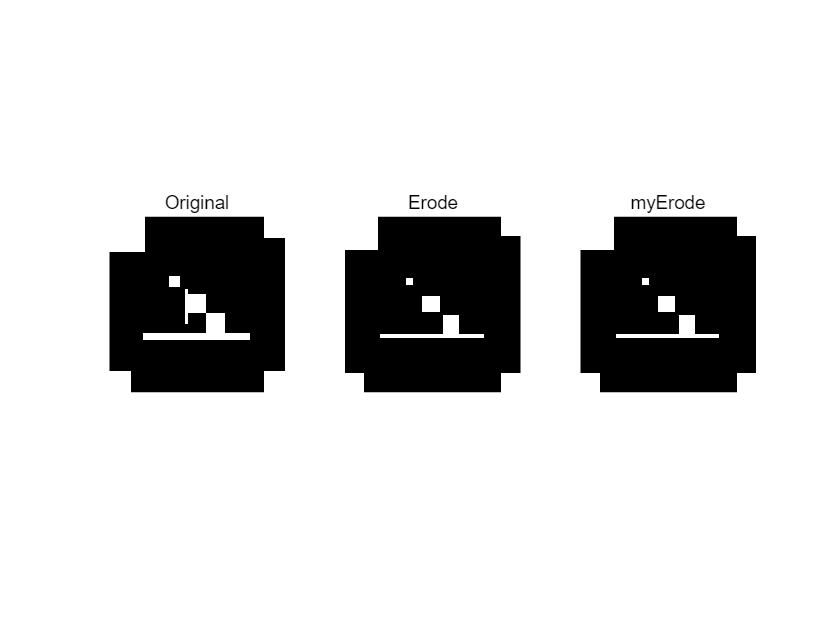

% 验证自己编写的腐蚀操作
clear;
% 生成一个图像类型为logical
I = false(100,100);
I(1:20,1:20) = true;
I(1:12, 89:100) = true;
I(89:100, 1:12) = true;
I(89:100, 89:100) = true;
I(45:55, 45:55) = true;
I(56:66, 56:66) = true;
I(42:61, 44:45) = true;
I(35:40, 35:40) = true;
I(67:70, 20:80) = true;
NHOOD = ones(3,3);
se = strel('arbitrary',NHOOD);
I_erode = imerode(I,se);
I_erode2 = my_imerode(I,NHOOD);
figure, subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), imshow(I_erode), title('Erode');
subplot(1,3,3), imshow(I_erode2), title('myErode');

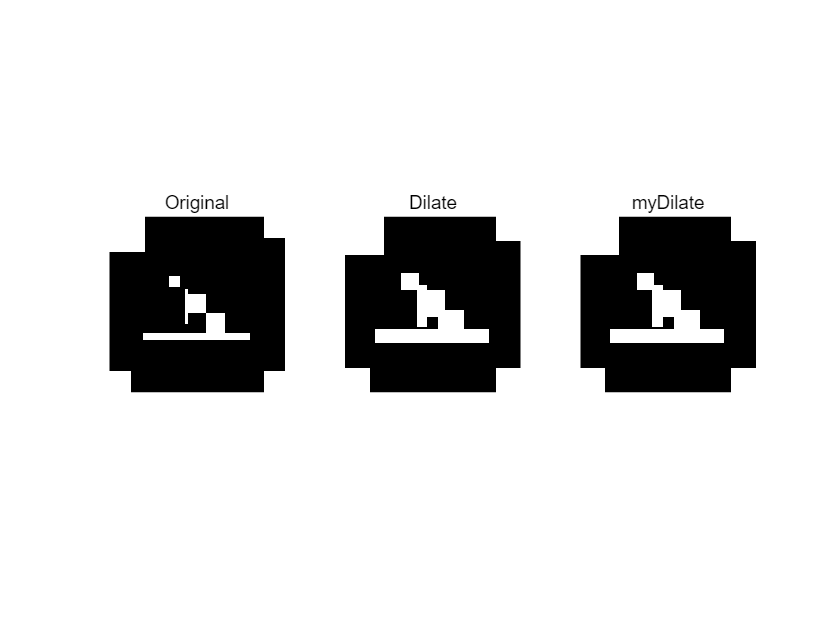


% 验证自己编写的膨胀操作
clear;
% 生成一个图像类型为logical
I = false(100,100);
I(1:20,1:20) = true;
I(1:12, 89:100) = true;
I(89:100, 1:12) = true;
I(89:100, 89:100) = true;
I(45:55, 45:55) = true;
I(56:66, 56:66) = true;
I(42:61, 44:45) = true;
I(35:40, 35:40) = true;
I(67:70, 20:80) = true;
NHOOD = ones(5,5);
se = strel('arbitrary',NHOOD);
I_dilate = imdilate(I,se);
I_dilate2 = my_imdilate(I,NHOOD);
figure, subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), imshow(I_dilate), title('Dilate');
subplot(1,3,3), imshow(I_dilate2), title('myDilate');